# Chapter 4: Time Response

syms s t C c
C(s)=(s+2)/(s*(s+5))

$$C(s) = \frac{s+2}{s\,\left(s+5\right)}$$

partfrac(C(s))

$$ans = \frac{3}{5\,\left(s+5\right)}+\frac{2}{5\,s}$$

c(t)=ilaplace(C(s))

$$c(t) = \frac{3\,{\mathrm{e}}^{-5\,t}}{5}+\frac{2}{5}$$


s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G=(s+2)/(s+5)

G =
 
  s + 2
  -----
  s + 5
 
Continuous-time transfer function.



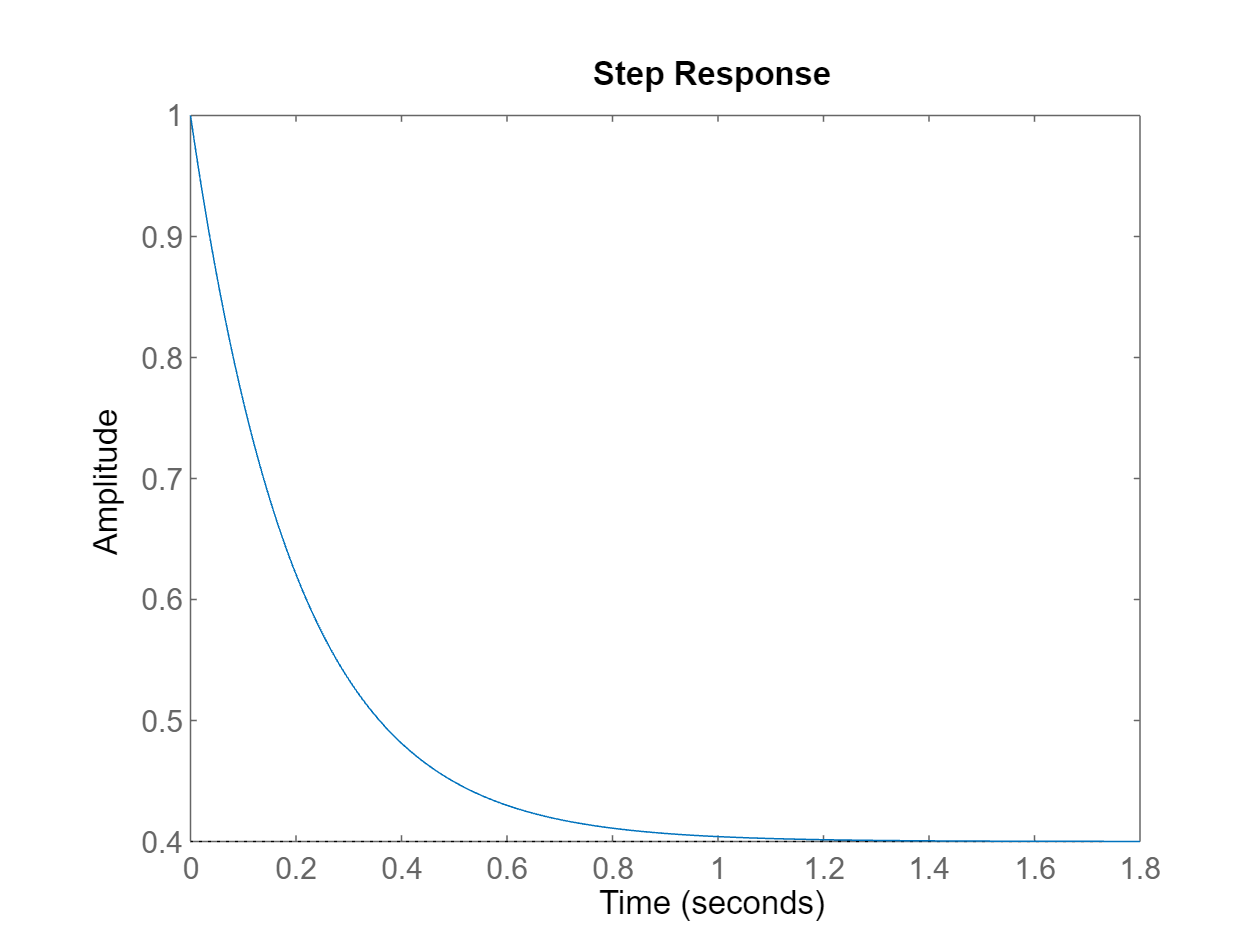

step(G)

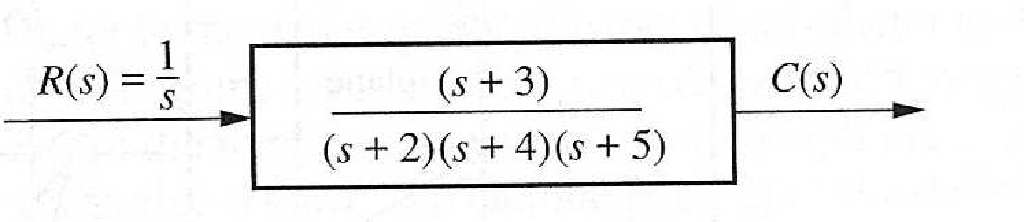

G=zpk([-3],[-2 -4 -5],1)

G =
 
        (s+3)
  -----------------
  (s+2) (s+4) (s+5)
 
Continuous-time zero/pole/gain model.



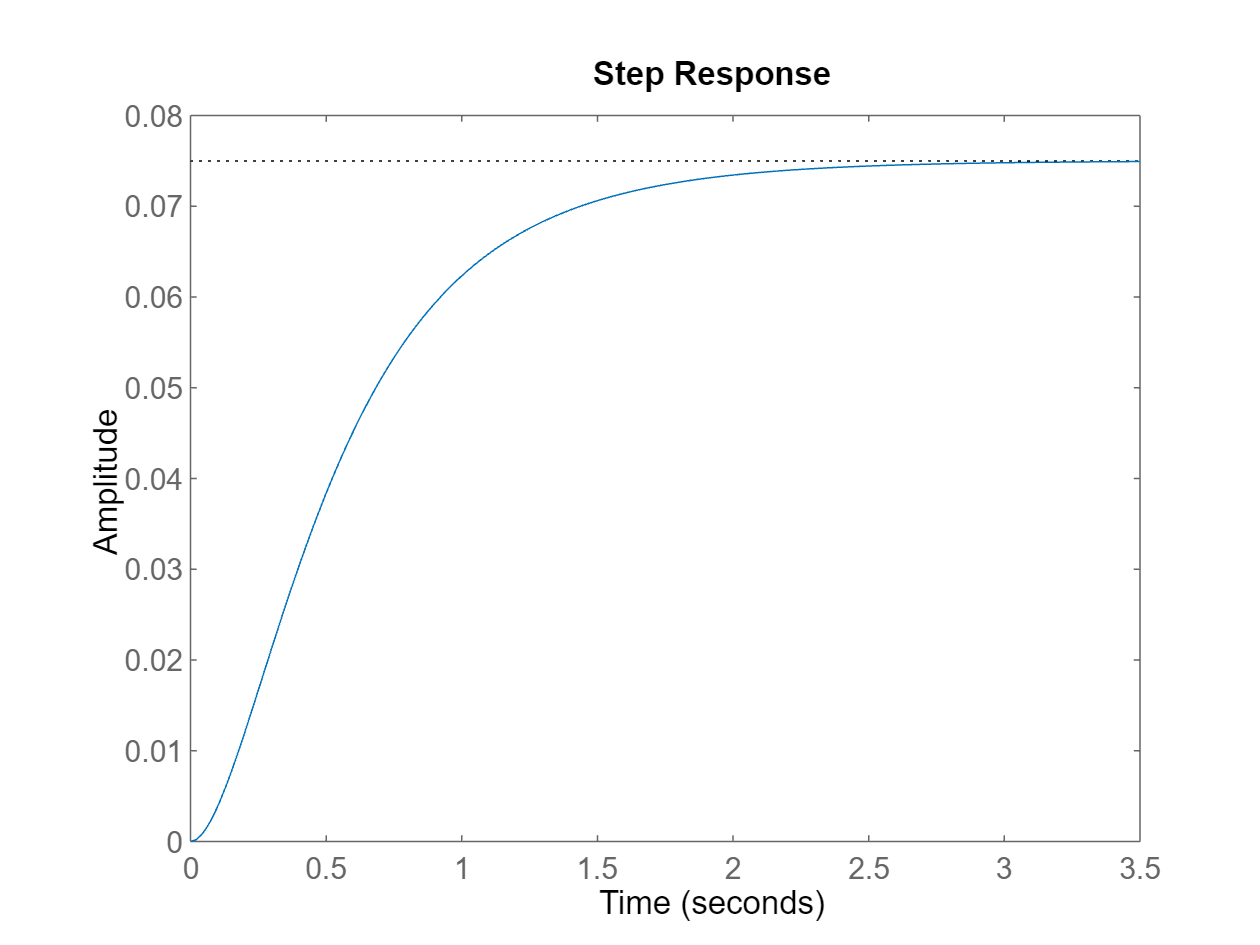

step(G)


[Num,Den] = tfdata(G);
syms s t
G_syms = poly2sym(cell2mat(Num),s)/poly2sym(cell2mat(Den),s)

$$G\_syms = \frac{s+3}{s^{3}+11\,s^{2}+38\,s+40}$$

partfrac(G_syms*1/s)

$$ans = \frac{2}{15\,\left(s+5\right)}-\frac{1}{8\,\left(s+4\right)}-\frac{1}{12\,\left(s+2\right)}+\frac{3}{40\,s}$$

ilaplace(G_syms*1/s)

$$ans = \frac{2\,{\mathrm{e}}^{-5\,t}}{15}-\frac{{\mathrm{e}}^{-4\,t}}{8}-\frac{{\mathrm{e}}^{-2\,t}}{12}+\frac{3}{40}$$

Consider example of Fig. 4.6 in the textbook

G=tf(5,[1 7])

G =
 
    5
  -----
  s + 7
 
Continuous-time transfer function.



is the actual transfer function.

G_guess=tf(5.54,[1 7.7])

G_guess =
 
   5.54
  -------
  s + 7.7
 
Continuous-time transfer function.



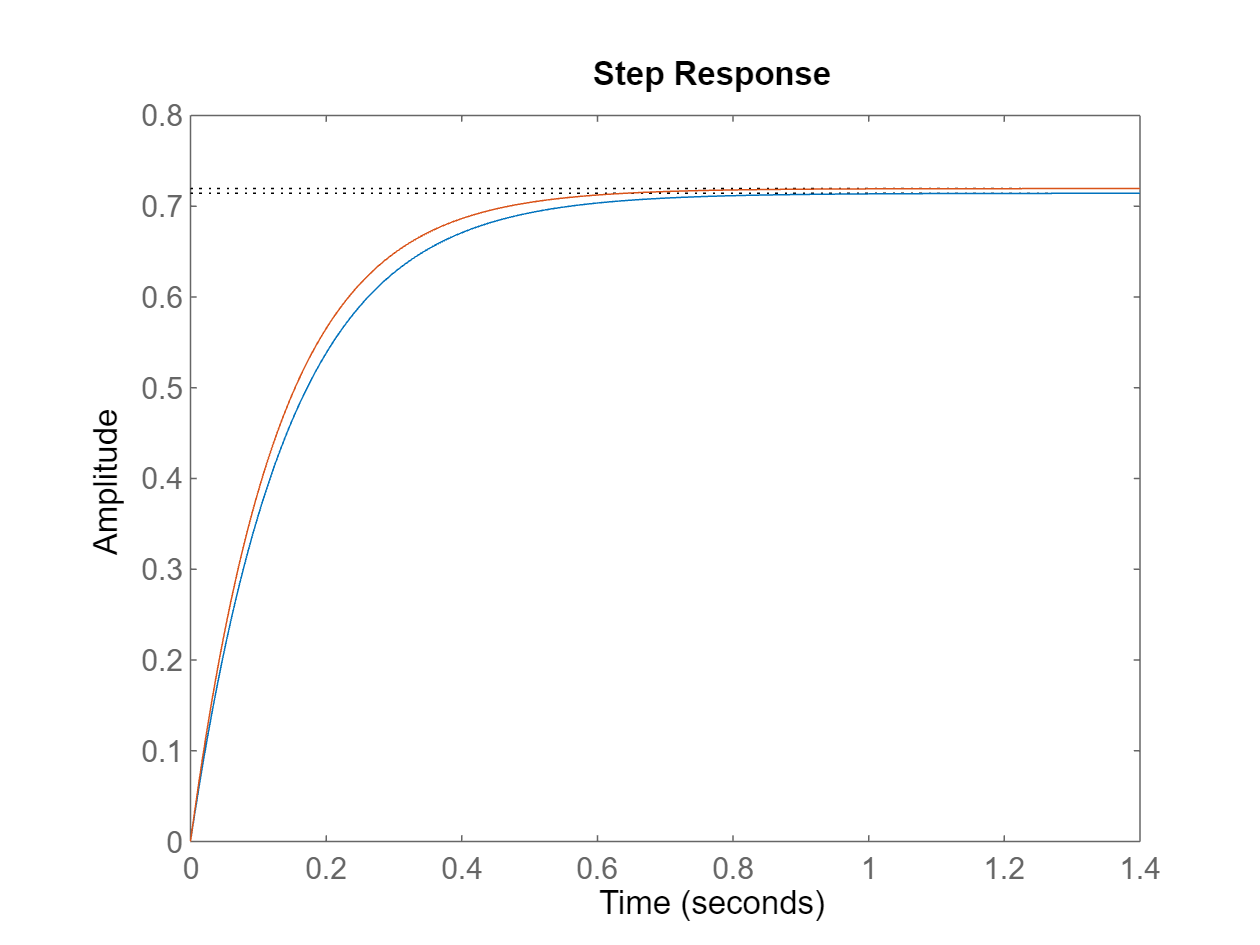

step(G,G_guess)

OK. So this is how we get an approximation by hand. How would we go about this in matlab with data? Here is an example from the 2021 Midterm.

Assume you have collected some data in the lab for an electric motor. In response to a 1V unit step input, the output rotational velocity of the motor in rad/s was recorded and stored in a data file which we will now load and plot: 

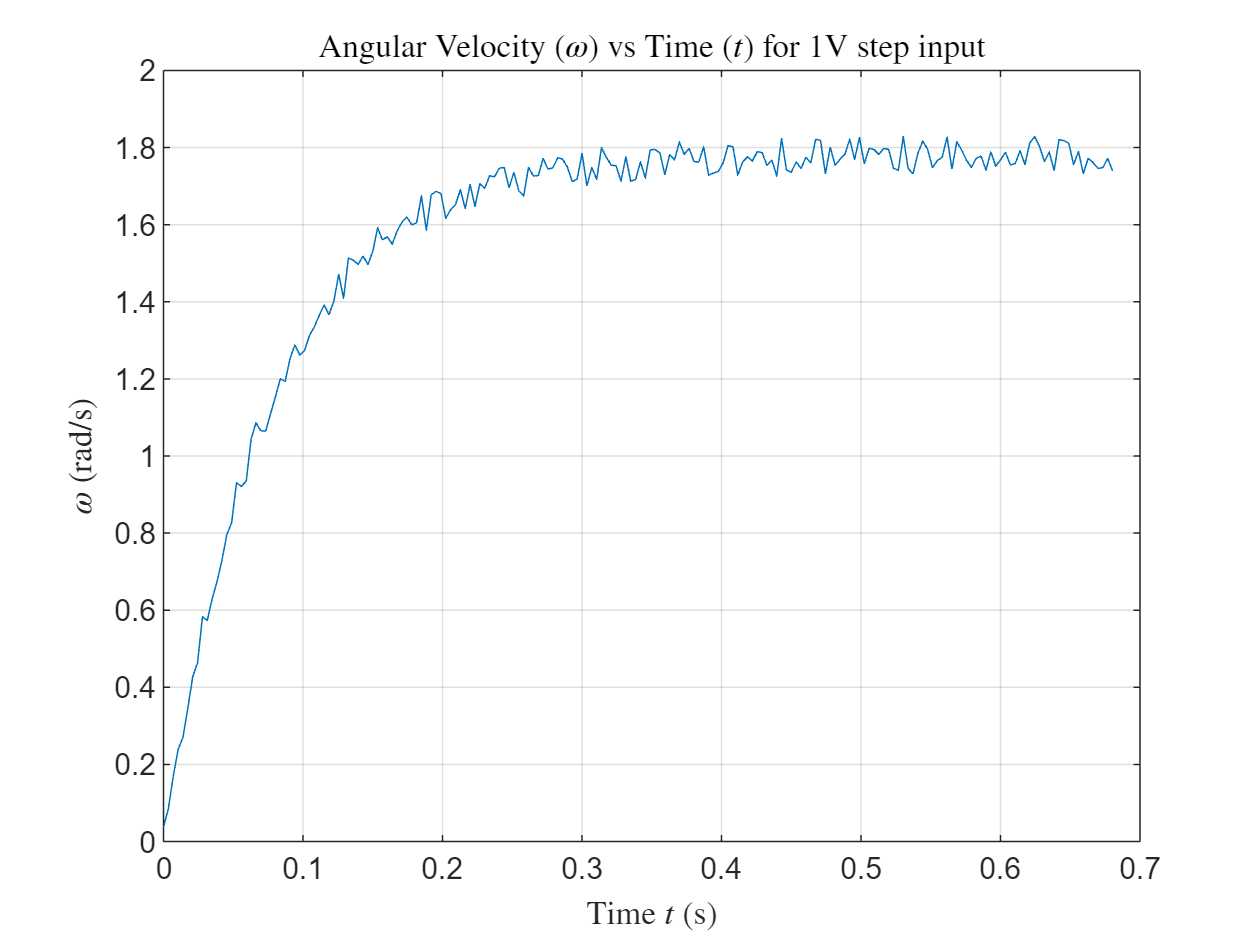

load("labdataMidterm21.mat")
plot(t,omega_measured)
xlabel('Time $t$ (s)','Interpreter',"latex")
ylabel('$\omega$ (rad/s)',"Interpreter","latex")
title("Angular Velocity ($\omega$) vs Time ($t$) for 1V step input","Interpreter","latex")
grid

You have to determine the approximate transfer function of the motor to match the data. Clever bunny that you are, you know that a good approximate linear model in this case is $G(s)=\frac{K_m}{s+\alpha}$. By any means create a model that fits the data reasonably well and then plot step response of you model against the data to visually compare your fitted model with the data.

%G_omega=   %Assign your model to this variable
%uncomment the commands below to plot the step response of your model and compare it
%to the data
%omega_guess=step(G_omega);
%plot(t,omega_measured,t,omega_guess)

*Solution:*

We can estimate the final value of the step response by taking the mean of the last 20 points of data as follows:

omega_ss=mean(omega_measured(length(omega_measured)-20:length(omega_measured)))

omega_ss = 1.7767

We can then figure out the approximate time when we are at  approximately $1-e^{-1}\approx$ 63% of the final value with the following code.

[m,i]=min(abs(omega_measured-omega_ss*(1-exp(-1))))

m = 0.0134

i = 23

tau=t(i)

tau = 0.0768

alpha=1/tau

alpha = 13.0288

K_m=alpha*omega_ss

K_m = 23.1484

G_guess=tf(K_m,[1 alpha])

G_guess =
 
    23.15
  ---------
  s + 13.03
 
Continuous-time transfer function.



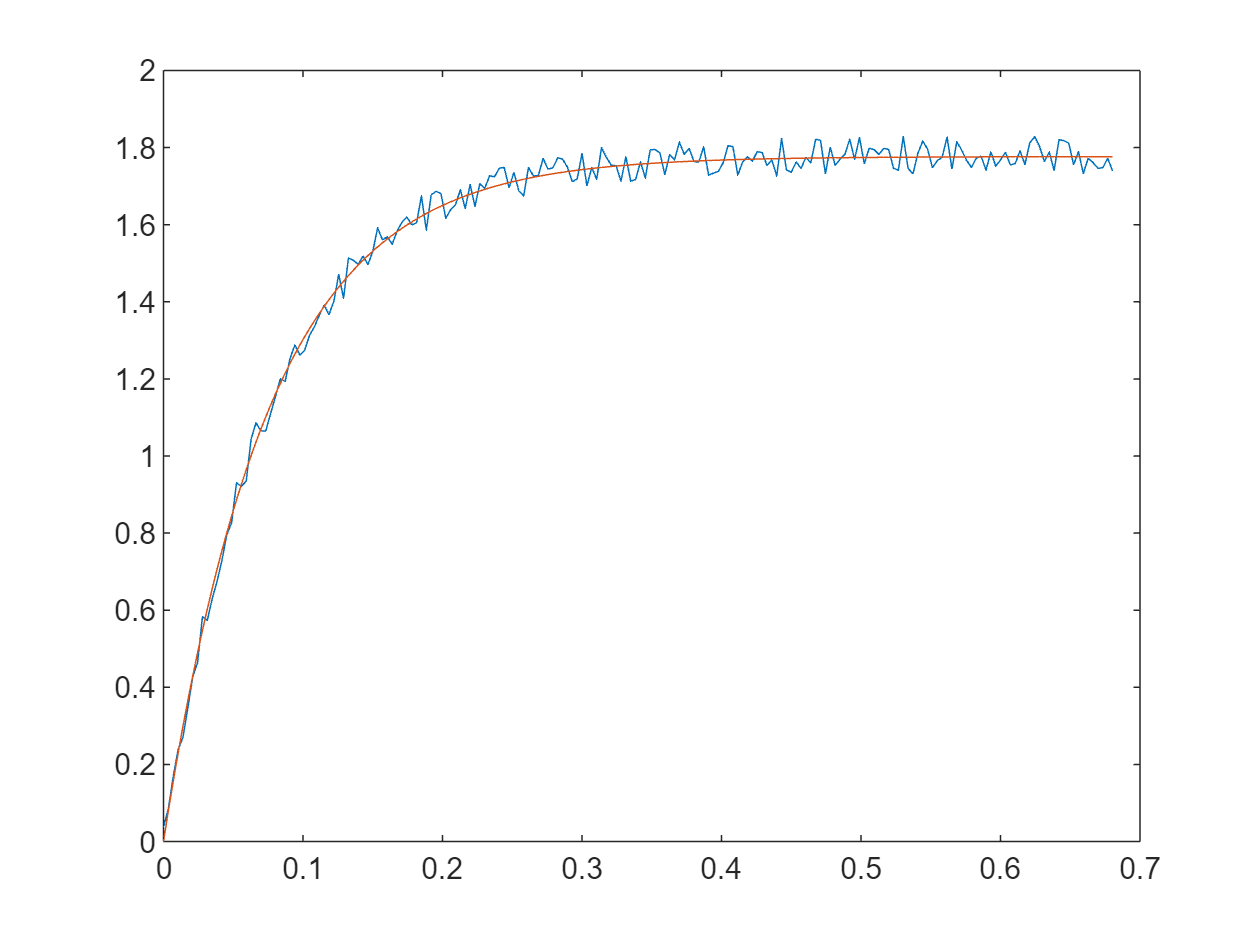

omega_guess=step(G_guess);
plot(t,omega_measured,t,omega_guess)

Alternatively if you want to be a little more sophisticated about it you can do a least squares fit of the first order transfer function to the data with the following commands.

data = iddata(omega_measured,ones(size(t)),t(2)-t(1));
G_omega = tfest(data,1,0)

G_omega =
  From input "u1" to output "y1":
    23.4
  ---------
  s + 13.15
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 92.57%                   
FPE: 0.0008238, MSE: 0.000799                    
 
Model Properties


Ok. We need to fix up the input and output to make the start of the step function clear. Since it is a first order model $n=1$pole, we need to prepend the input and output with at least $n+1$ zeros. We therefore modify the previous command as shown below.

data = iddata([zeros(2,1);omega_measured],[zeros(2,1);ones(size(t))],t(2)-t(1));
G_omega = tfest(data,1,0)

G_omega =
  From input "u1" to output "y1":
    23.39
  ---------
  s + 13.14
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 93.14%                   
FPE: 0.0008153, MSE: 0.0007909                   
 
Model Properties


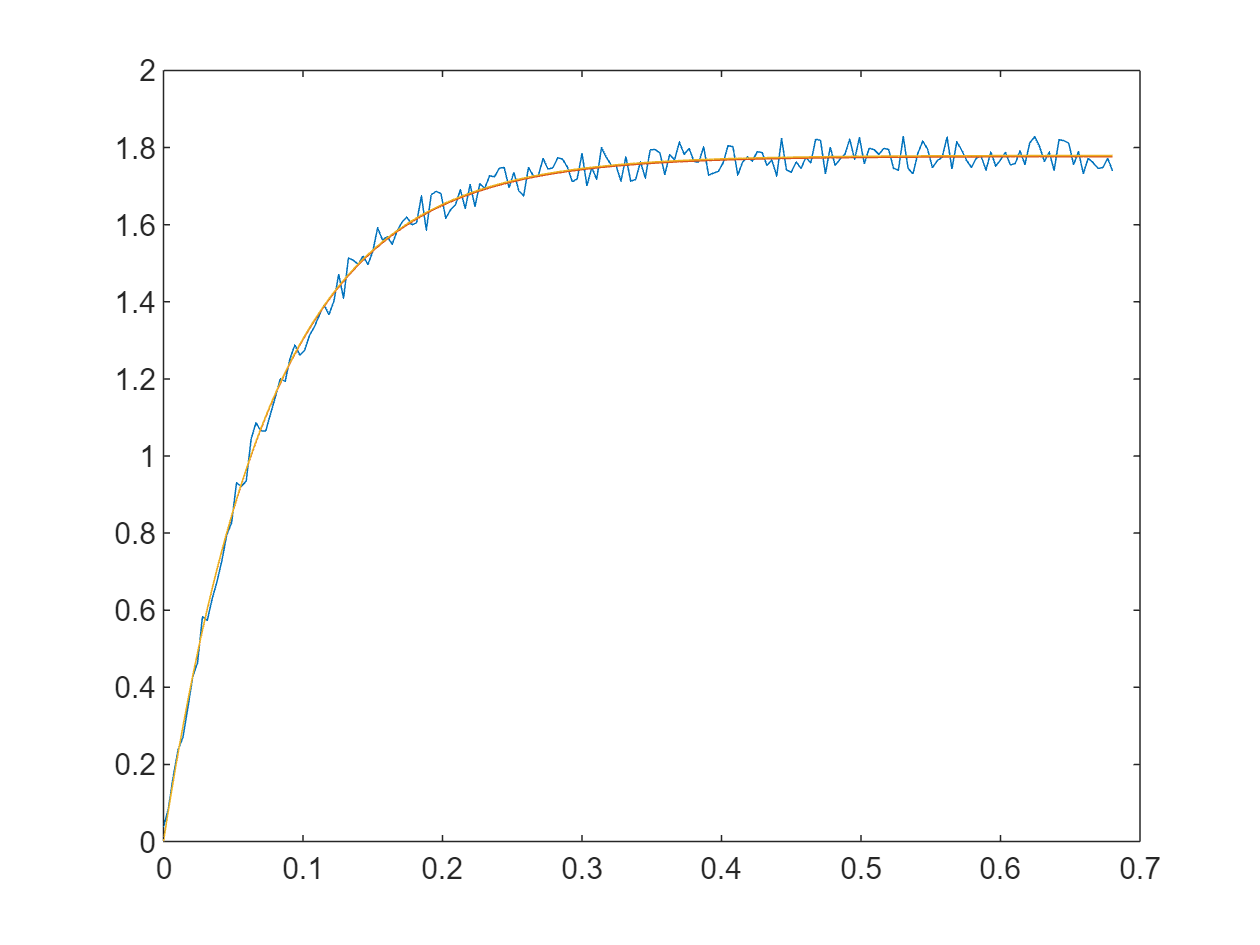

omega_guess2=step(G_omega);
plot(t,omega_measured,t,omega_guess,t,omega_guess2)

*NOTE: The commands used to generate the data were as folllows:*

G=tf([23.5],[1 13.2])

G =
 
    23.5
  --------
  s + 13.2
 
Continuous-time transfer function.



%[omega,t]=step(G);
%noise=rand(size(omega))-0.5;
%omega_measured=y+noise;
%save('labdataFinal20.mat','t','omega_measured')

Let's see how well we did considering the noise.

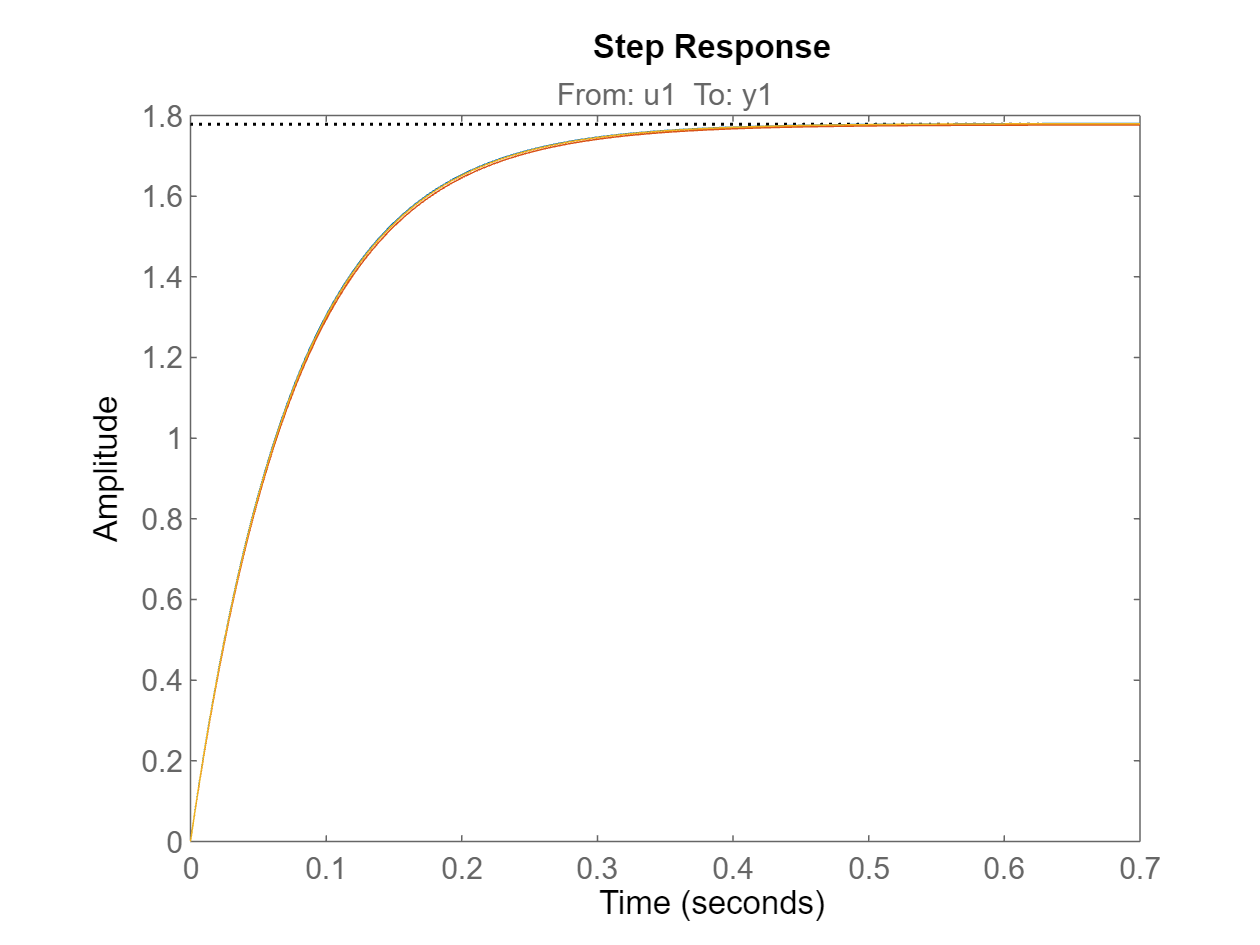

step(G, G_guess, G_omega)

**Marking scheme**:

- 2 marks for pole location $\alpha$ (1 for method + 1 for result of $\pm0.4$ of actual)

- 2 marks for gain $M$(1 for method + 1 for result $\pm 0.2$ of actual)

- 1 mark for fit of step response within graph 

**2nd order systems examples:**

syms s t c

**Overdamped**

Gover=tf(9,[1 9 9])

Gover =
 
        9
  -------------
  s^2 + 9 s + 9
 
Continuous-time transfer function.



roots([1 9 9])

ans =    -7.8541
   -1.1459


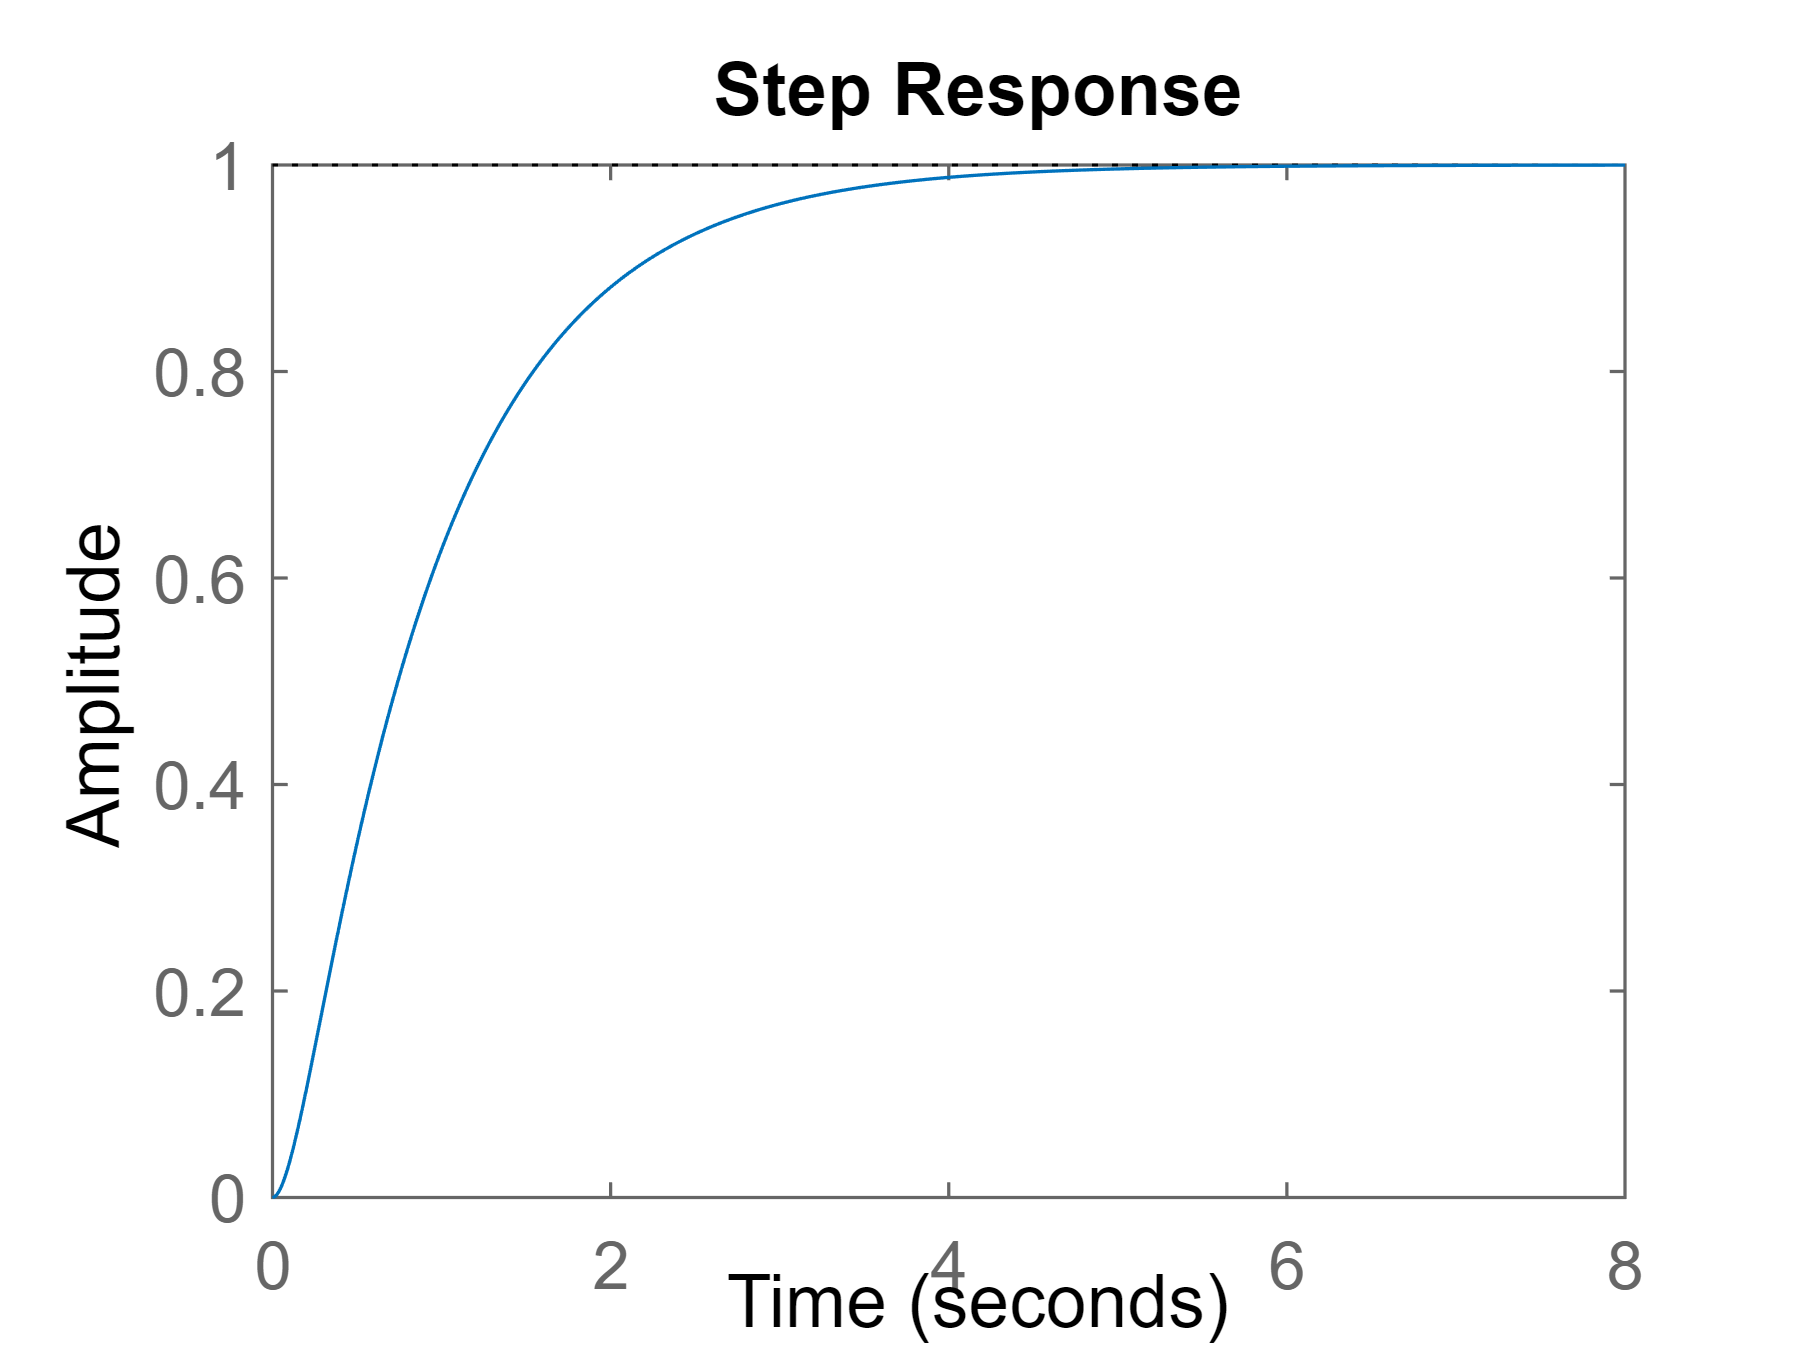

step(Gover)

[Num,Den] = tfdata(Gover)

Num = 1×1 cell array
    {[0 0 9]}


Den = 1×1 cell array
    {[1 9 9]}


Gover_syms = poly2sym(cell2mat(Num),s)/poly2sym(cell2mat(Den),s)
partfrac(Gover_syms*1/s)
c(t)=ilaplace(Gover_syms*1/s)
c(t)=rewrite(c(t), 'exp')
vpa(c(t),3)
c(t)=expand(c(t))
c(t)=simplify(c(t))
vpa(c(t),3)
C(s)=9/(s*(s+7.854)*(s+1.146))
partfrac(C(s))
vpa(partfrac(C(s)),3)

**Critically Damped**

C(s)=9/(s*(s^2+6*s+9))
partfrac(C(s))
syms c(t)
c(t)=ilaplace(C(s))

**Underdamped Response**

C(s)=9/(s*(s^2+2*s+9))
partfrac(C(s))
c(t)=ilaplace(C(s))

### 2nd order systems

Consider a second order system of the form:


$$G(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_n s+\omega_n^2}$$


syms s t omega_n zeta G C R c
G(s)=collect(omega_n^2/(s^2+2*zeta*omega_n*s+omega_n^2),s)

In response to a step input we have

R(s)=1/s
C(s)=G(s)*R(s)
partfrac(C)

Completing the square of the denominator we have

eq1=collect(s^2+2*zeta*omega_n*s+omega_n^2,s)==(s+zeta*omega_n)^2-(zeta*omega_n)^2+omega_n^2
%collect(eq1,s)
simplify(eq1)
assume(zeta,'real')
assumeAlso(zeta>0 & zeta<1)
assume(omega_n, 'real')
assumeAlso(omega_n>0)
c(t)=ilaplace(C(s))

omega_n=3

omega_n = 3

zeta=0.3

zeta = 0.3000

s=tf('s');
G2nd=omega_n^2/(s^2+2*zeta*omega_n*s+omega_n^2)

G2nd =
 
         9
  ---------------
  s^2 + 1.8 s + 9
 
Continuous-time transfer function.



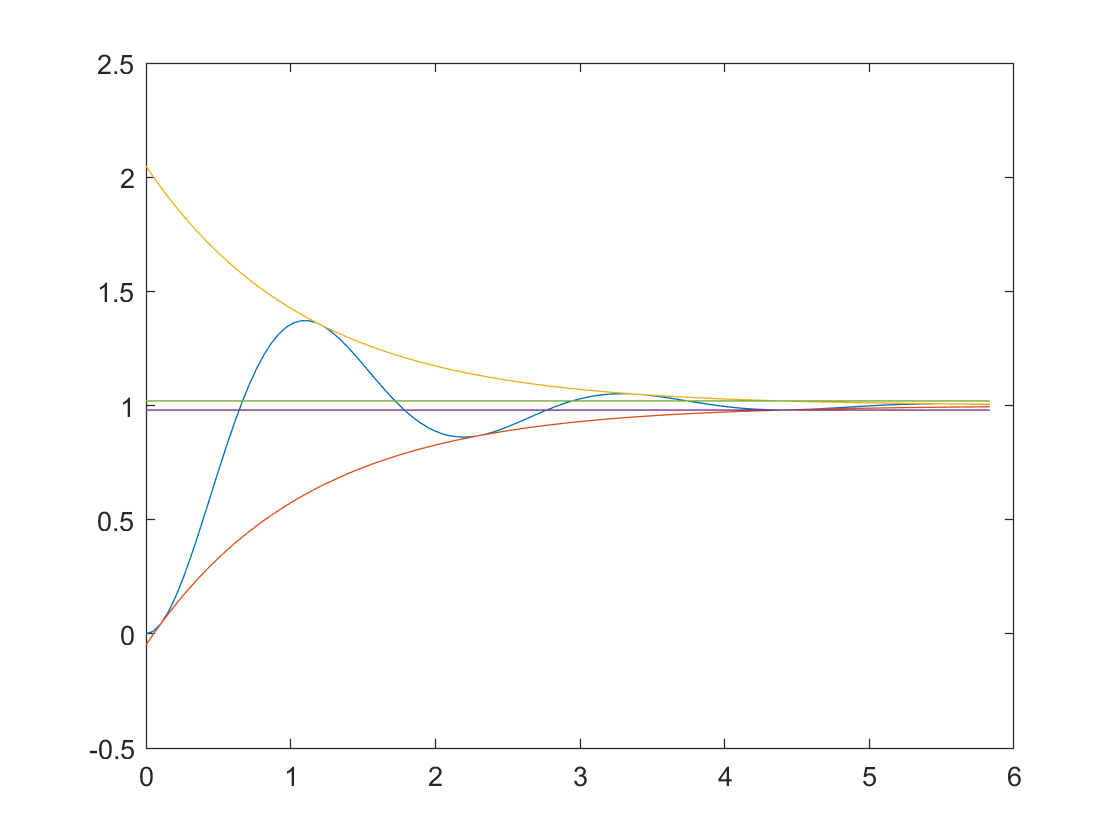

[y,t]=step(G2nd);
lb=1-(1/sqrt(1-zeta^2))*exp(-zeta*omega_n*t);
ub=1+(1/sqrt(1-zeta^2))*exp(-zeta*omega_n*t);
l2per=ones(size(t))*0.98;
u2per=ones(size(t))*1.02;
plot(t,y,t,lb,t,ub,t,l2per,t,u2per)

Now let's compare what happens when we change $\zeta=0.5$ to increase the damping ratio.

zeta=0.5

zeta = 0.5000

G2nd05=tf([omega_n^2],[1 2*zeta*omega_n omega_n^2])

G2nd05 =
 
        9
  -------------
  s^2 + 3 s + 9
 
Continuous-time transfer function.



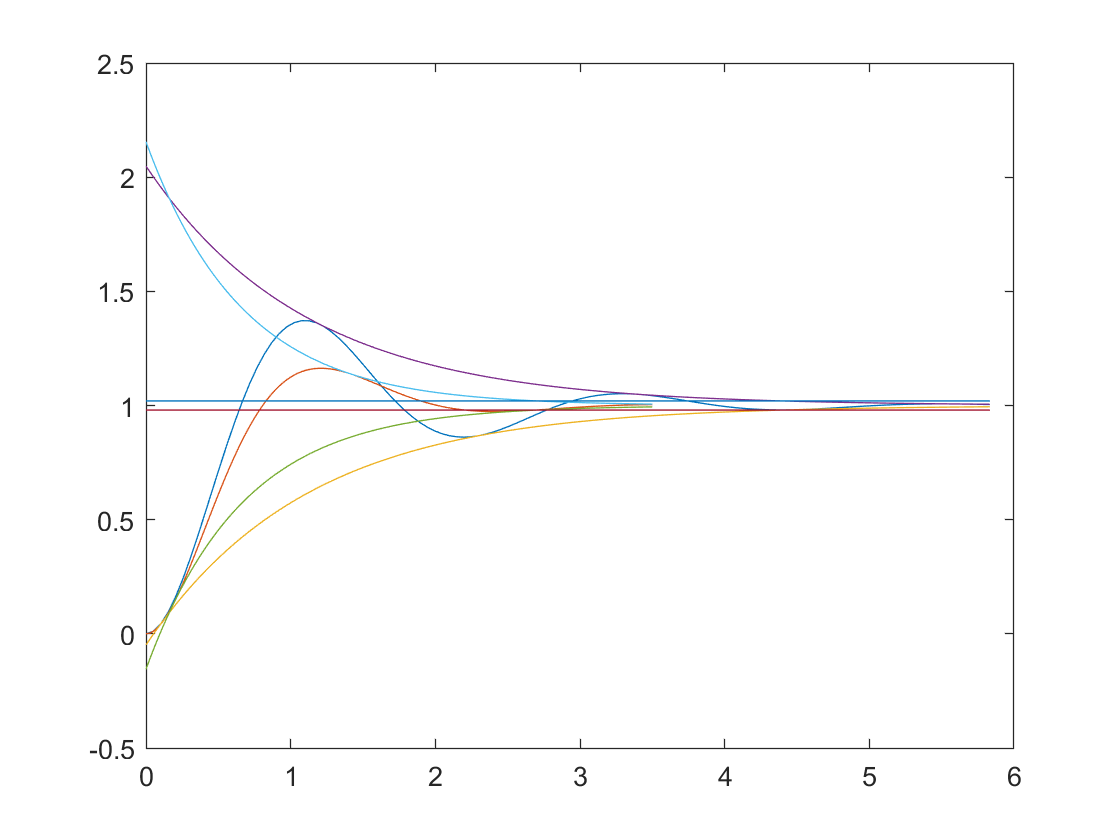

[y05,t05]=step(G2nd05);
lb05=1-(1/sqrt(1-zeta^2))*exp(-zeta*omega_n*t05);
ub05=1+(1/sqrt(1-zeta^2))*exp(-zeta*omega_n*t05);
plot(t,y,t05,y05,t,lb,t,ub,t05,lb05,t05,ub05,t,l2per,t,u2per)

Now compare with system with $\zeta=0.1$

zeta=0.1

zeta = 0.1000

G2nd01=tf([omega_n^2],[1 2*zeta*omega_n omega_n^2])

G2nd01 =
 
         9
  ---------------
  s^2 + 0.6 s + 9
 
Continuous-time transfer function.



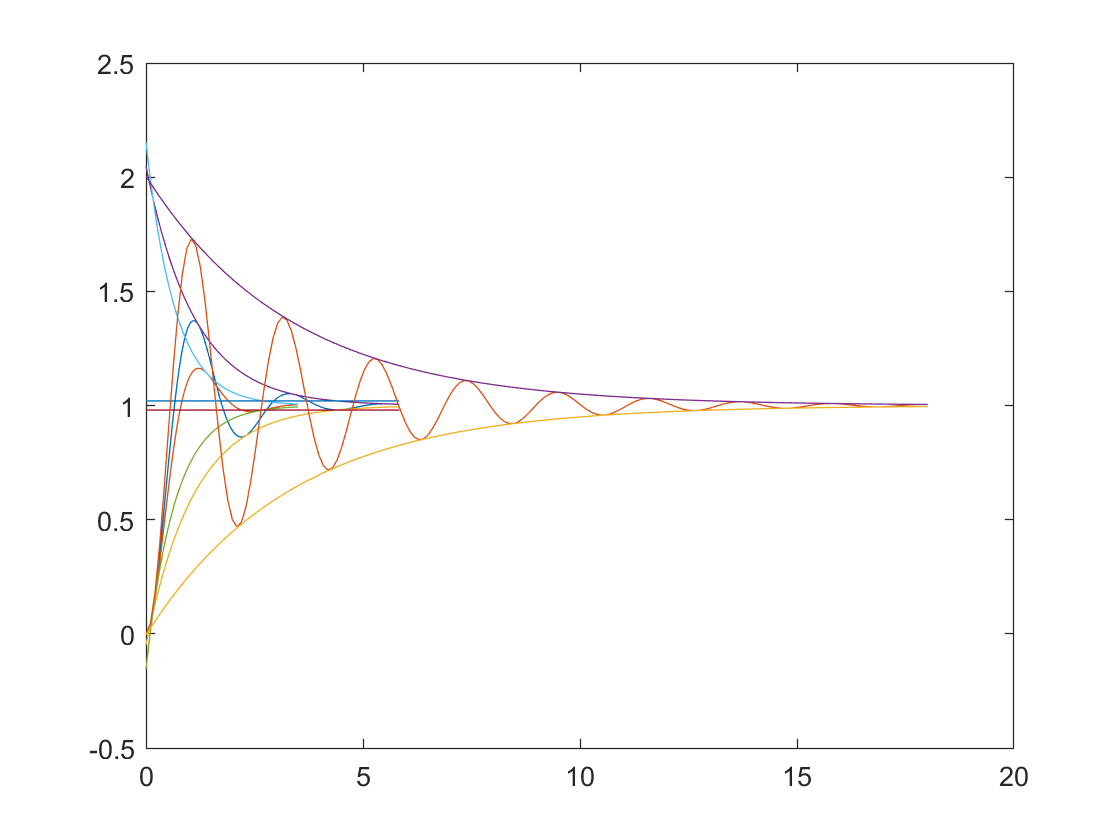

[y01,t01]=step(G2nd01);
lb01=1-(1/sqrt(1-zeta^2))*exp(-zeta*omega_n*t01);
ub01=1+(1/sqrt(1-zeta^2))*exp(-zeta*omega_n*t01);
plot(t,y,t05,y05,t,lb,t,ub,t05,lb05,t05,ub05,t,l2per,t,u2per,t01,y01,t01,lb01,t01,ub01)

### **Example 3 pole system**

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



G_1=24.542/(s^2 + 4*s + 24.542)

G_1 =
 
        24.54
  -----------------
  s^2 + 4 s + 24.54
 
Continuous-time transfer function.



pole(G_1)

ans =   -2.0000 + 4.5323i
  -2.0000 - 4.5323i


G_2=10*24.542/((s+10)*(s^2 + 4*s + 24.542))

G_2 =
 
              245.4
  ------------------------------
  s^3 + 14 s^2 + 64.54 s + 245.4
 
Continuous-time transfer function.



pole(G_2)

ans =  -10.0000 + 0.0000i
  -2.0000 + 4.5323i
  -2.0000 - 4.5323i


G_3=3*24.542/((s+3)*(s^2 + 4*s + 24.542))

G_3 =
 
              73.63
  -----------------------------
  s^3 + 7 s^2 + 36.54 s + 73.63
 
Continuous-time transfer function.



pole(G_3)

ans =   -2.0000 + 4.5323i
  -2.0000 - 4.5323i
  -3.0000 + 0.0000i


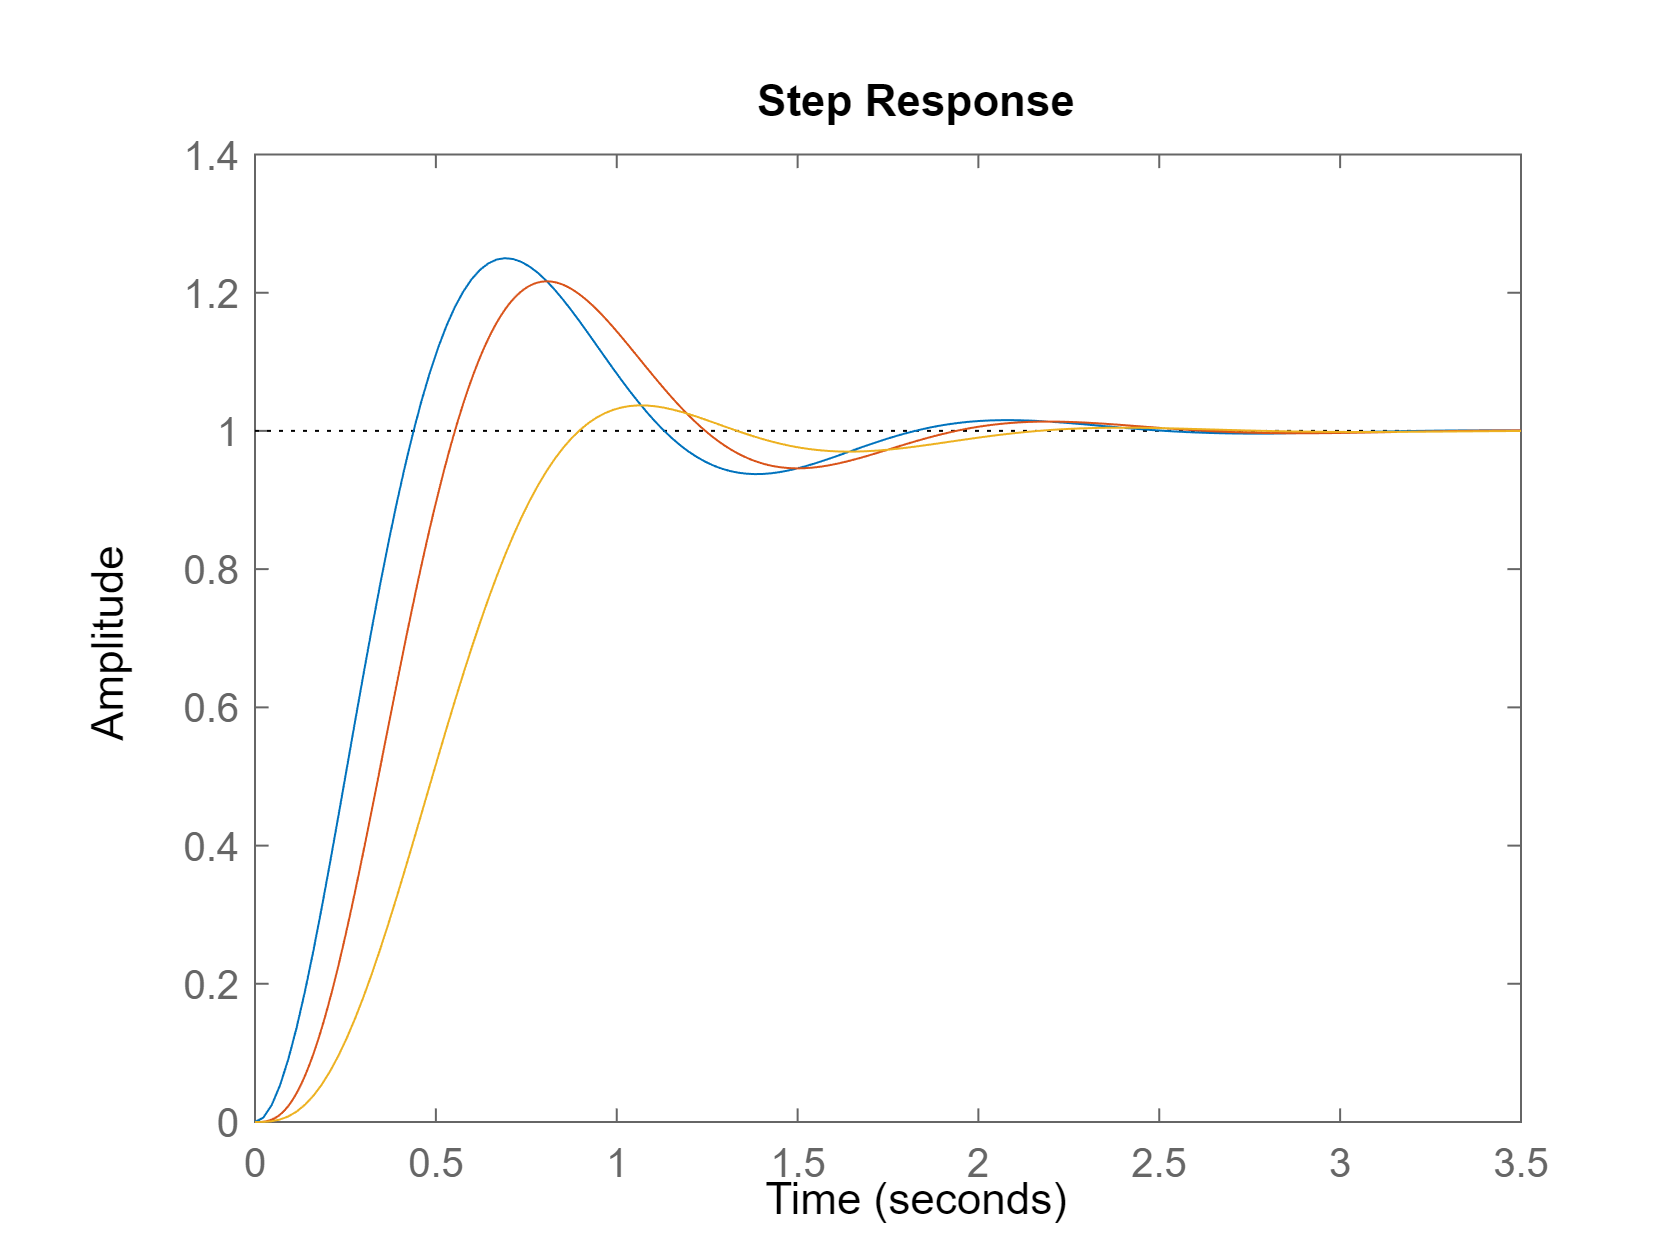

step(G_1,G_2,G_3)

### System Response with Additional Poles

syms s a b c K G G_cl omega_n zeta
G_HO=b*c/((s^2+a*s+b)*(s+c))
C=G_HO/s

So the partial fractions expantion of $C(s)$ will be of the form:


$$C(s) = \frac{bc}{s(s^2+as + b)(s+c)} = \frac{A}{s} + \frac{Bs +C}{s^2+as + b} + \frac{D}{s+c}$$


    partfrac(C)

If you were going to do the partial fractions expansion by hand you could solve for $D$ above by multiplying both sides of the equation by $(s+c)$ and then substituting $s=-c$ (i.e. $D=\left.(s+c)C(s)\right|_{s=-c}$). You can do this in matlab with the commands:

D=C*(s+c)
D=subs(D,s,-c)

The farther the pole at $s=-c$ is to the left, the less of an impact the pole at $s=-c$ has on the system output since


$$\lim_{c\rightarrow\infty}D=\lim_{c\rightarrow\infty}-\frac{b}{c^2 -a\,c+b}=0$$


limit(D,c,inf)

### **Effect of Zeros**

What if the second order system:

s=tf('s')
G_1=24.542/(s^2 + 4*s + 24.542)

 has a zero at $s=-1$

G_z1=24.542*(s+1)/(s^2 + 4*s + 24.542)

s =
 
  s
 
Continuous-time transfer function.



step(G_1,G_z1)

G_1 =
 
        24.54
  -----------------
  s^2 + 4 s + 24.54
 
Continuous-time transfer function.



What happens when the zero moves to $s=-10$

G_z10=24.542/10*(s+10)/(s^2 + 4*s + 24.542)

G_z1 =
 
   24.54 s + 24.54
  -----------------
  s^2 + 4 s + 24.54
 
Continuous-time transfer function.



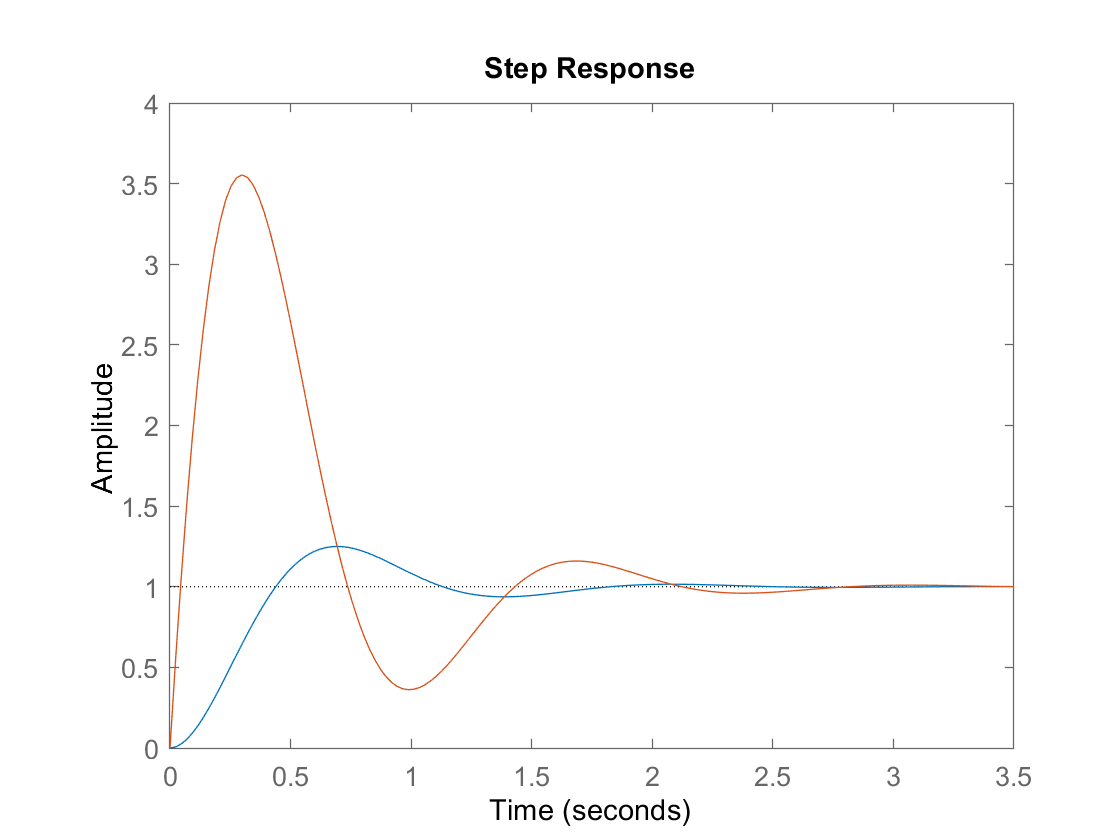

step(G_1,G_z1,G_z10)

G_z30=24.542/30*(s+30)/(s^2 + 4*s + 24.542)
pole(G_z30)

G_z10 =
 
   2.454 s + 24.54
  -----------------
  s^2 + 4 s + 24.54
 
Continuous-time transfer function.



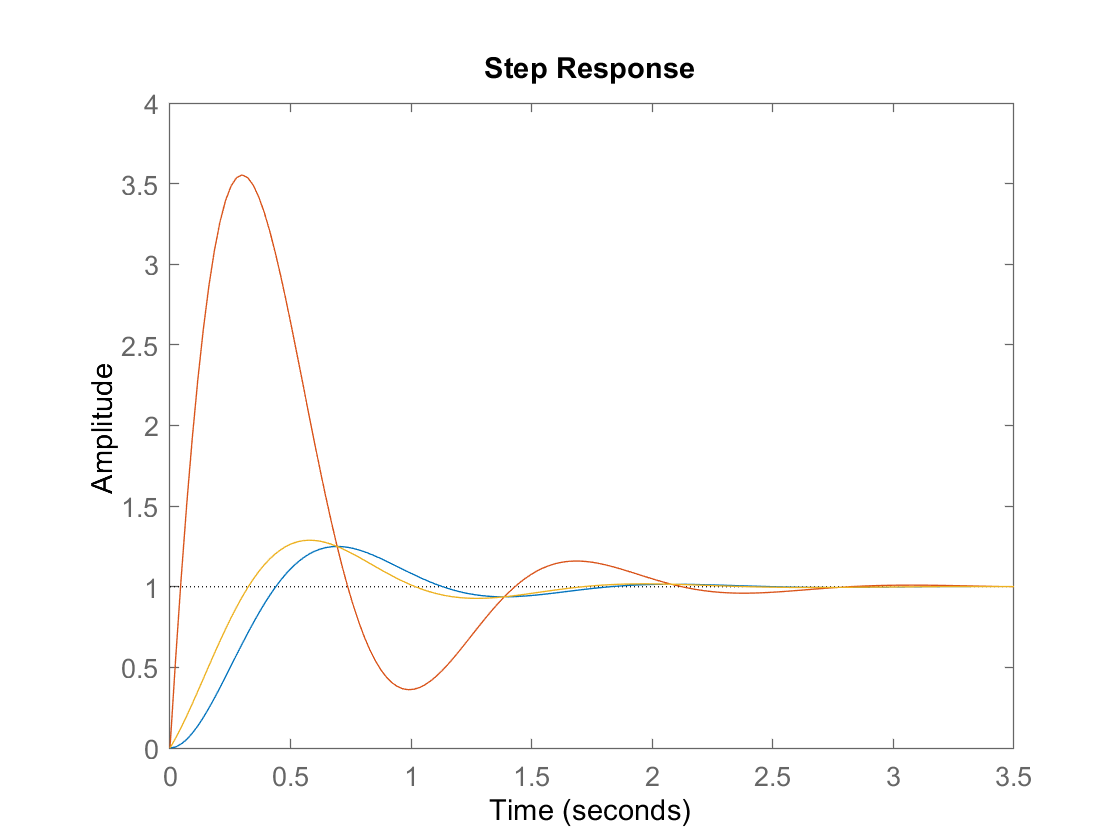

zero(G_z30)

step(G_1,G_z1,G_z10,G_z30)

G_z30 =
 
  0.8181 s + 24.54
  -----------------
  s^2 + 4 s + 24.54
 
Continuous-time transfer function.



**Nonminimum-phase systems**

What if, instead of a zero at $s=-1$, the system has a zero at $s=1$?

G_nonMinPhase=-24.542*(s-1)/(s^2 + 4*s + 24.542)

ans =   -2.0000 + 4.5323i
  -2.0000 - 4.5323i


step(G_1,G_nonMinPhase)

ans = -30

#### Pole Zero Cancellations

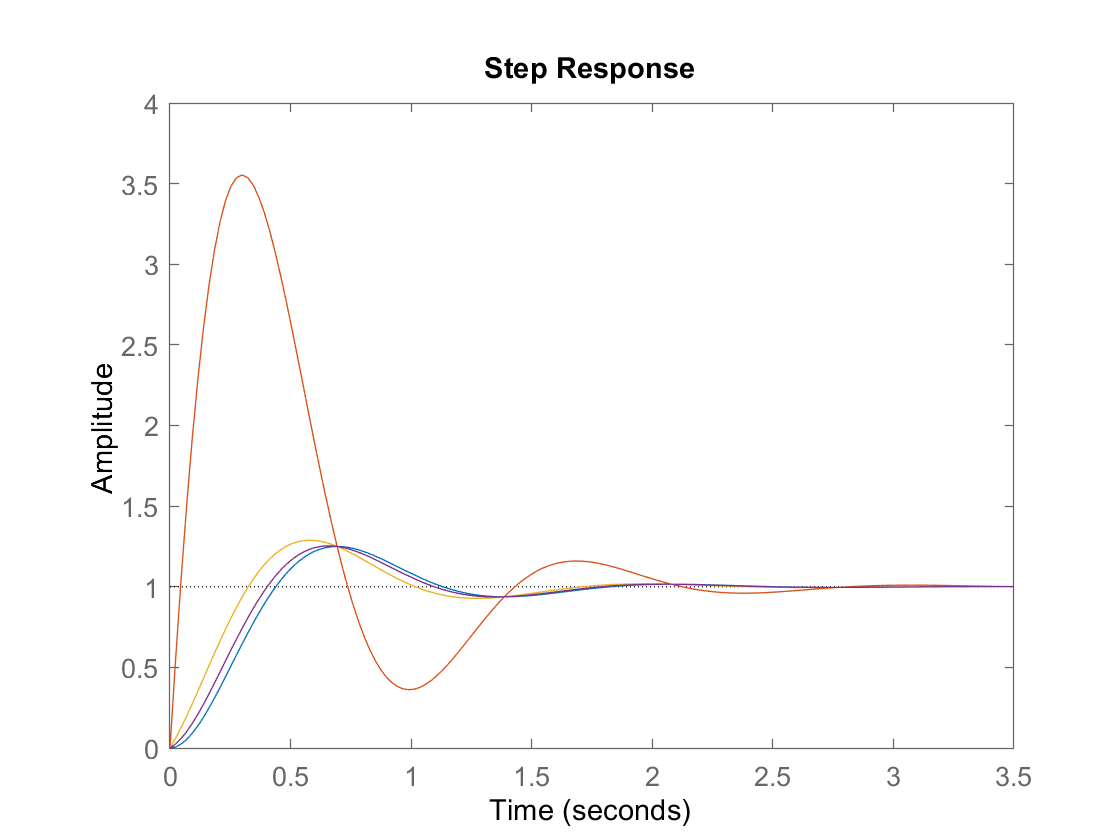

syms s C

C(s)=26.25*(s + 4)/(s*(s + 4.01)*(s + 5)*(s + 6))
partfrac(C(s))
vpa(partfrac(C(s)),3)

G_nonMinPhase =
 
  -24.54 s + 24.54
  -----------------
  s^2 + 4 s + 24.54
 
Continuous-time transfer function.



OK. Let's do this numerically

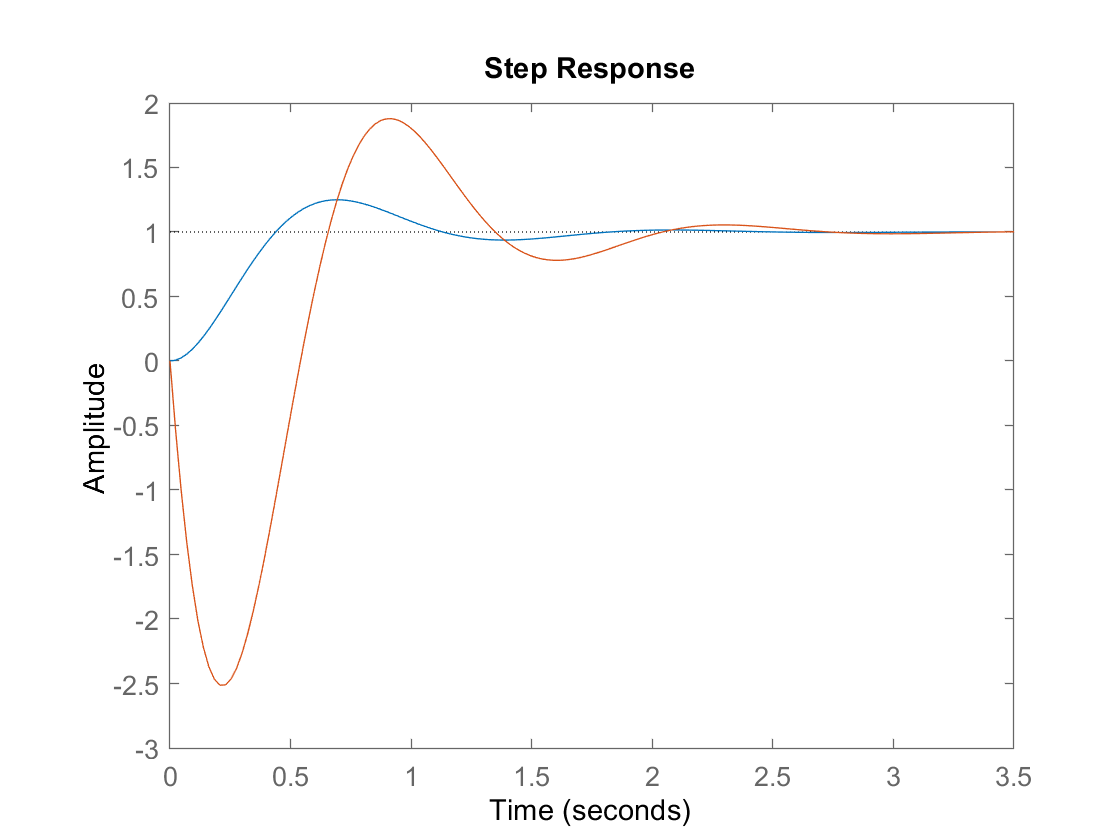

s=tf('s')

G2nd=26.25/((s + 5)*(s + 6))
G=26.25*(s + 4)/((s + 4.01)*(s + 5)*(s + 6))
step(G2nd,G)

The pole at $s=-4.01$ is effectively cancelled by the zero at $s=-4$. 

What happens though when there is near pole/zero cancellation in the Right Half Plane (RHP)? i.e. an unstable pole and zero in the RHP.

Gunstable=26.25*(s - 4)/((s - 4.001)*(s + 5)*(s + 6))
step(G,Gunstable,1)

Not too bad to start. What happens a little further out?

step(G,Gunstable,3)

What is going on? Let's look at the time domain response for this unstable system

syms s t G_unstable C_unstable
G_unstable(s)=26.25*(s - 4)/((s - 4.001)*(s + 5)*(s + 6))

For step input $R(s)=\frac{1}{s}$

C_unstable(s)=G_unstable(s)/s

s =
 
  s
 
Continuous-time transfer function.



partfrac(C_unstable(s))

G2nd =
 
       26.25
  ---------------
  s^2 + 11 s + 30
 
Continuous-time transfer function.



ilaplace(C_unstable)

G =
 
            26.25 s + 105
  ---------------------------------
  s^3 + 15.01 s^2 + 74.11 s + 120.3
 
Continuous-time transfer function.



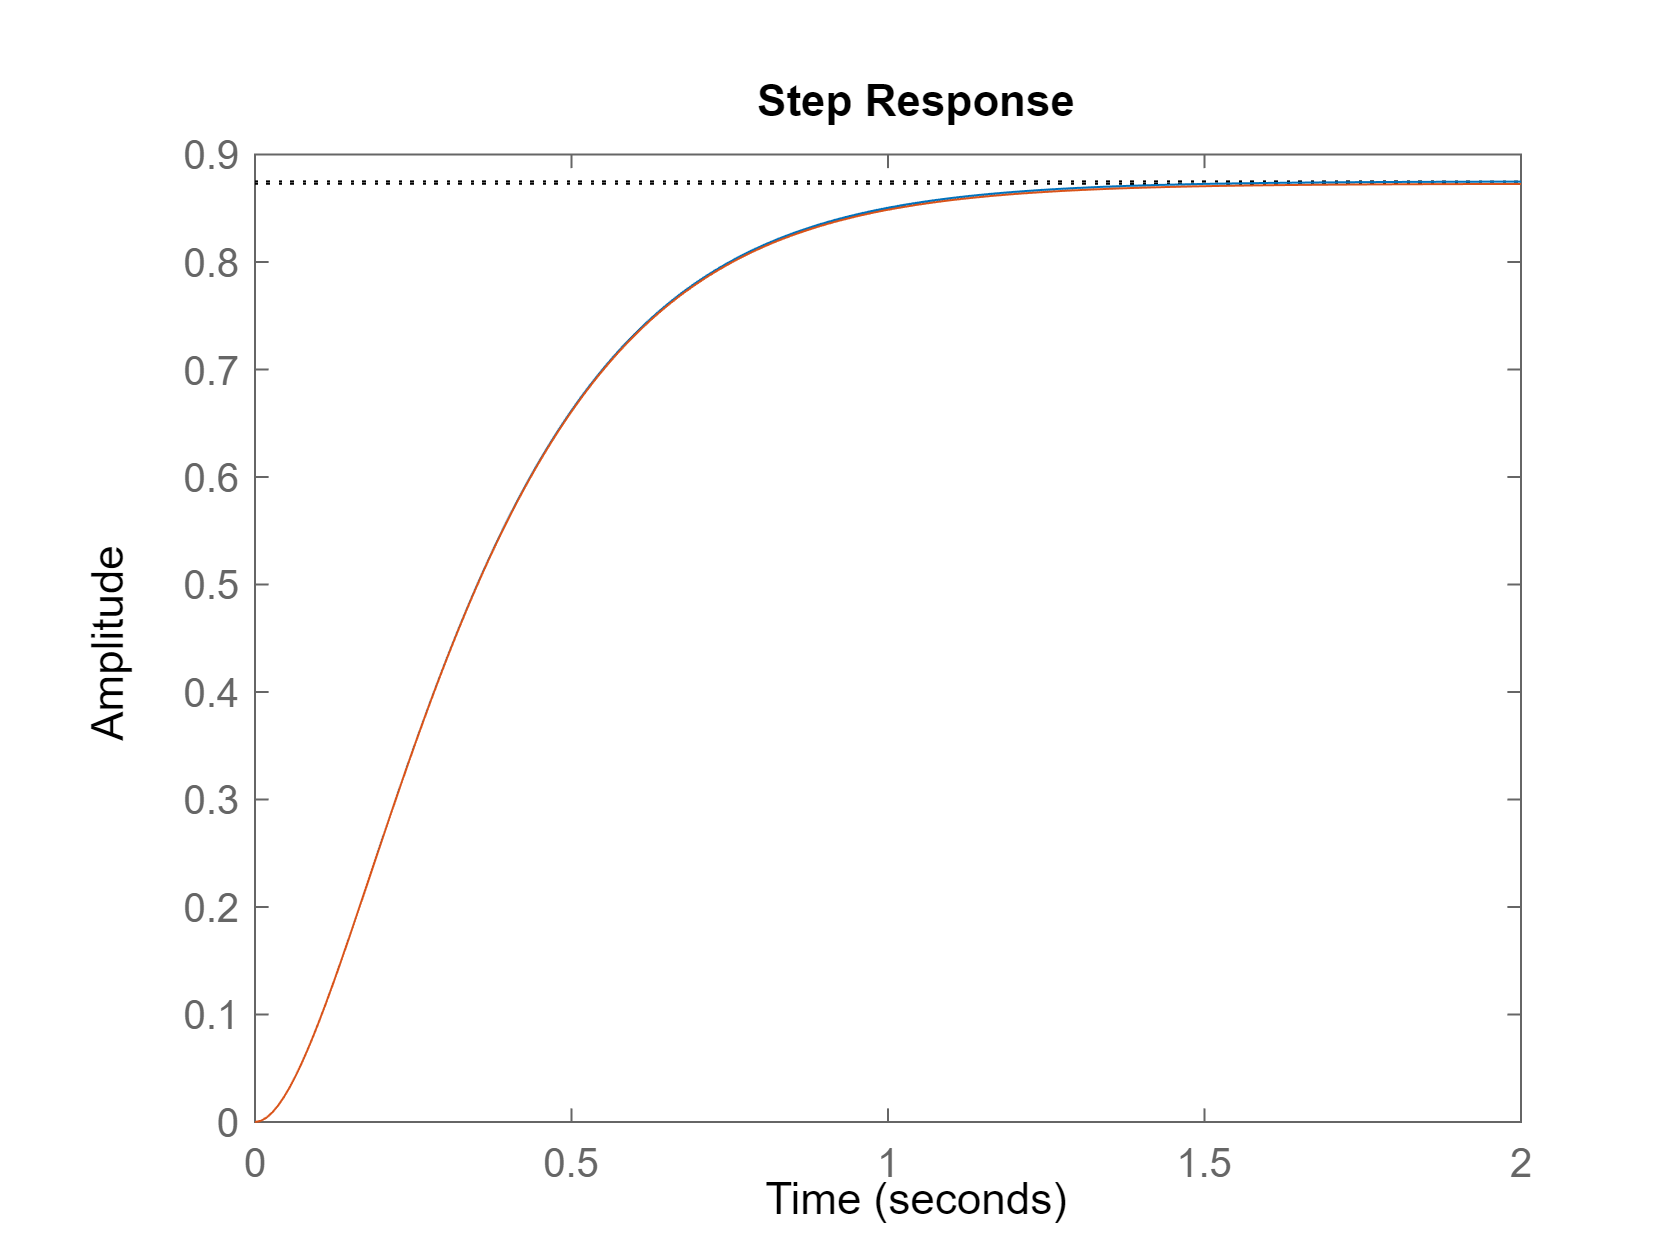

vpa(ans,4)

The $e^{4.01 t}$ term grows without bound and even though it inital contribution is limited by the small scaling factor coeffcient.

Eventually the positive exponential overwhelms the constant multiplier. 

#### Analysis and Design of Feedback Systems

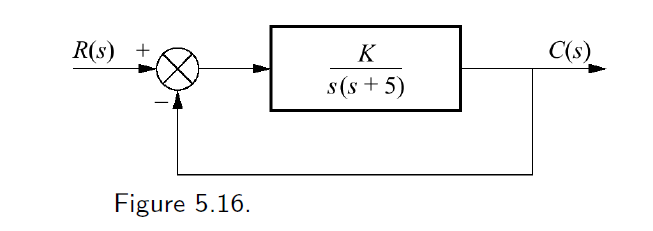    

syms s a K G G_cl omega_n zeta

Gunstable =
 
           26.25 s - 105
  -------------------------------
  s^3 + 6.999 s^2 - 14.01 s - 120
 
Continuous-time transfer function.



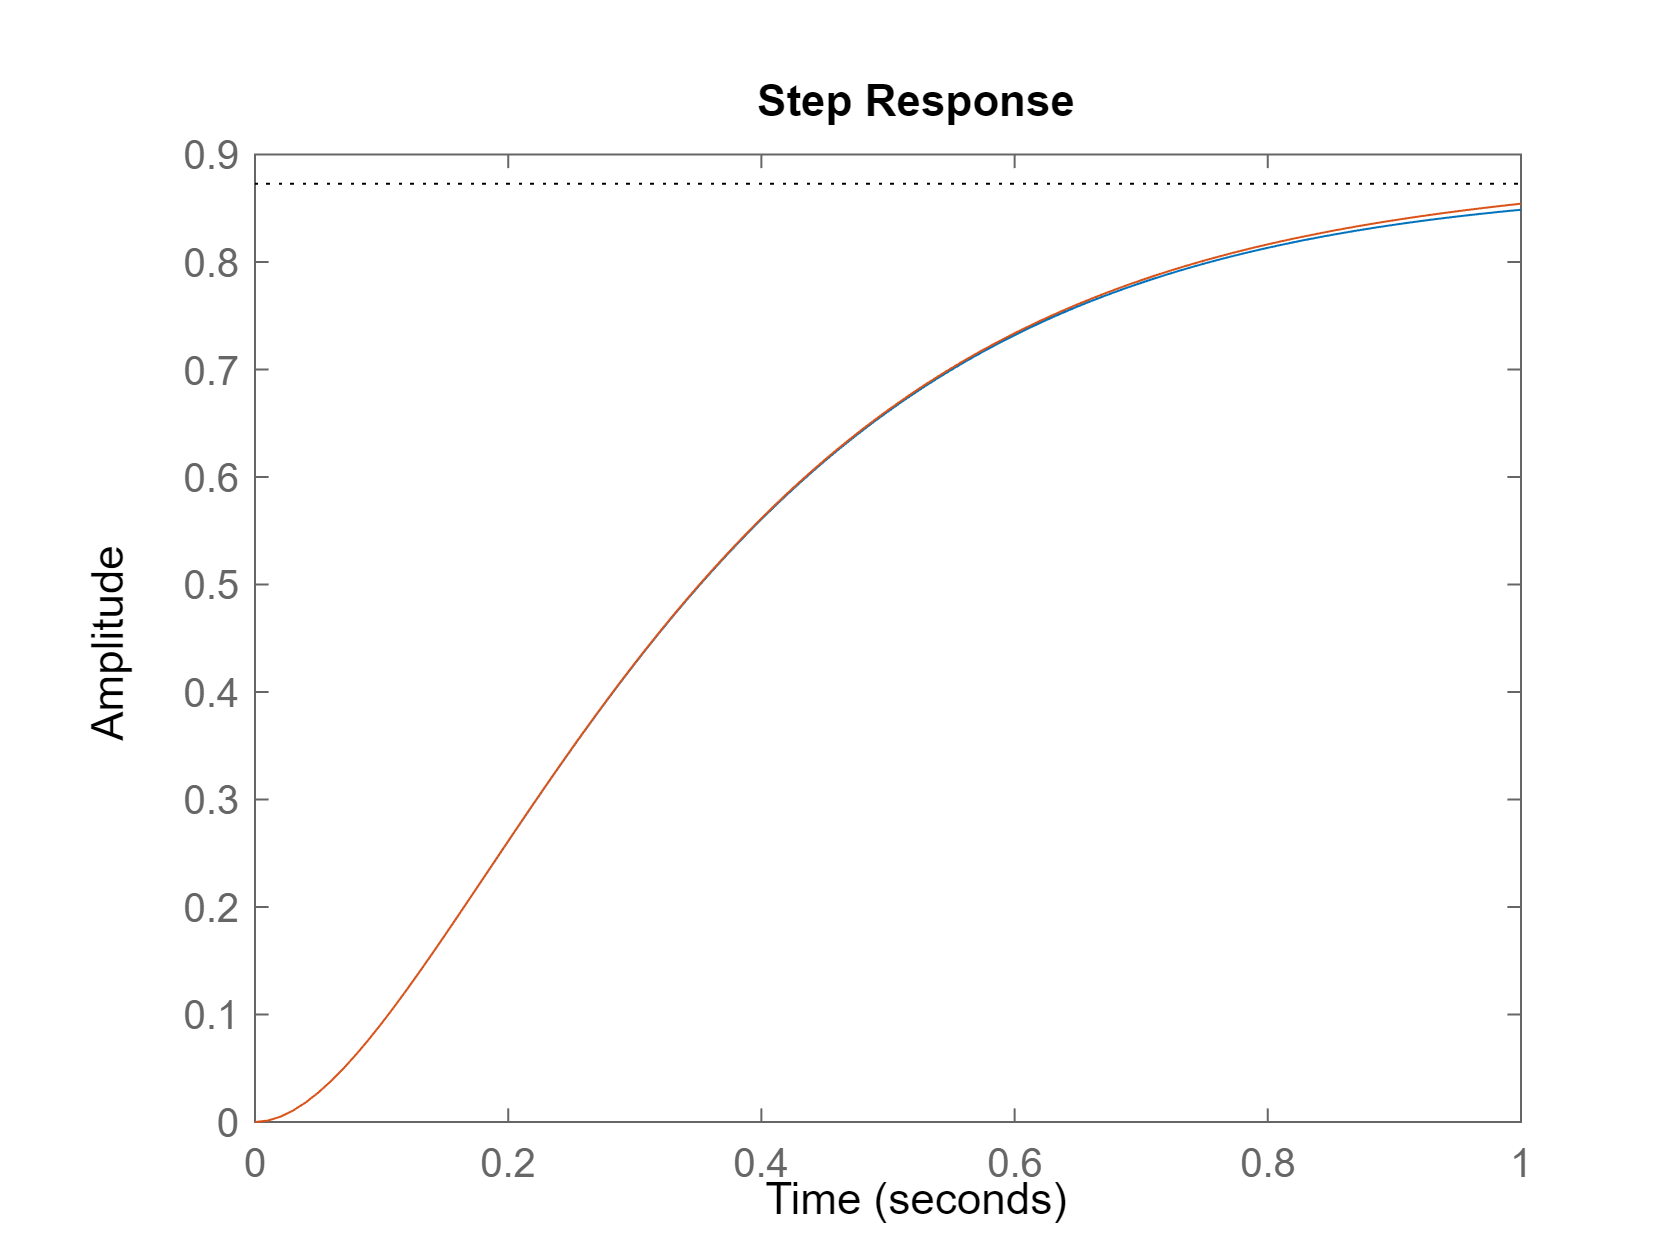

G(s)=K/(s*(s+a))

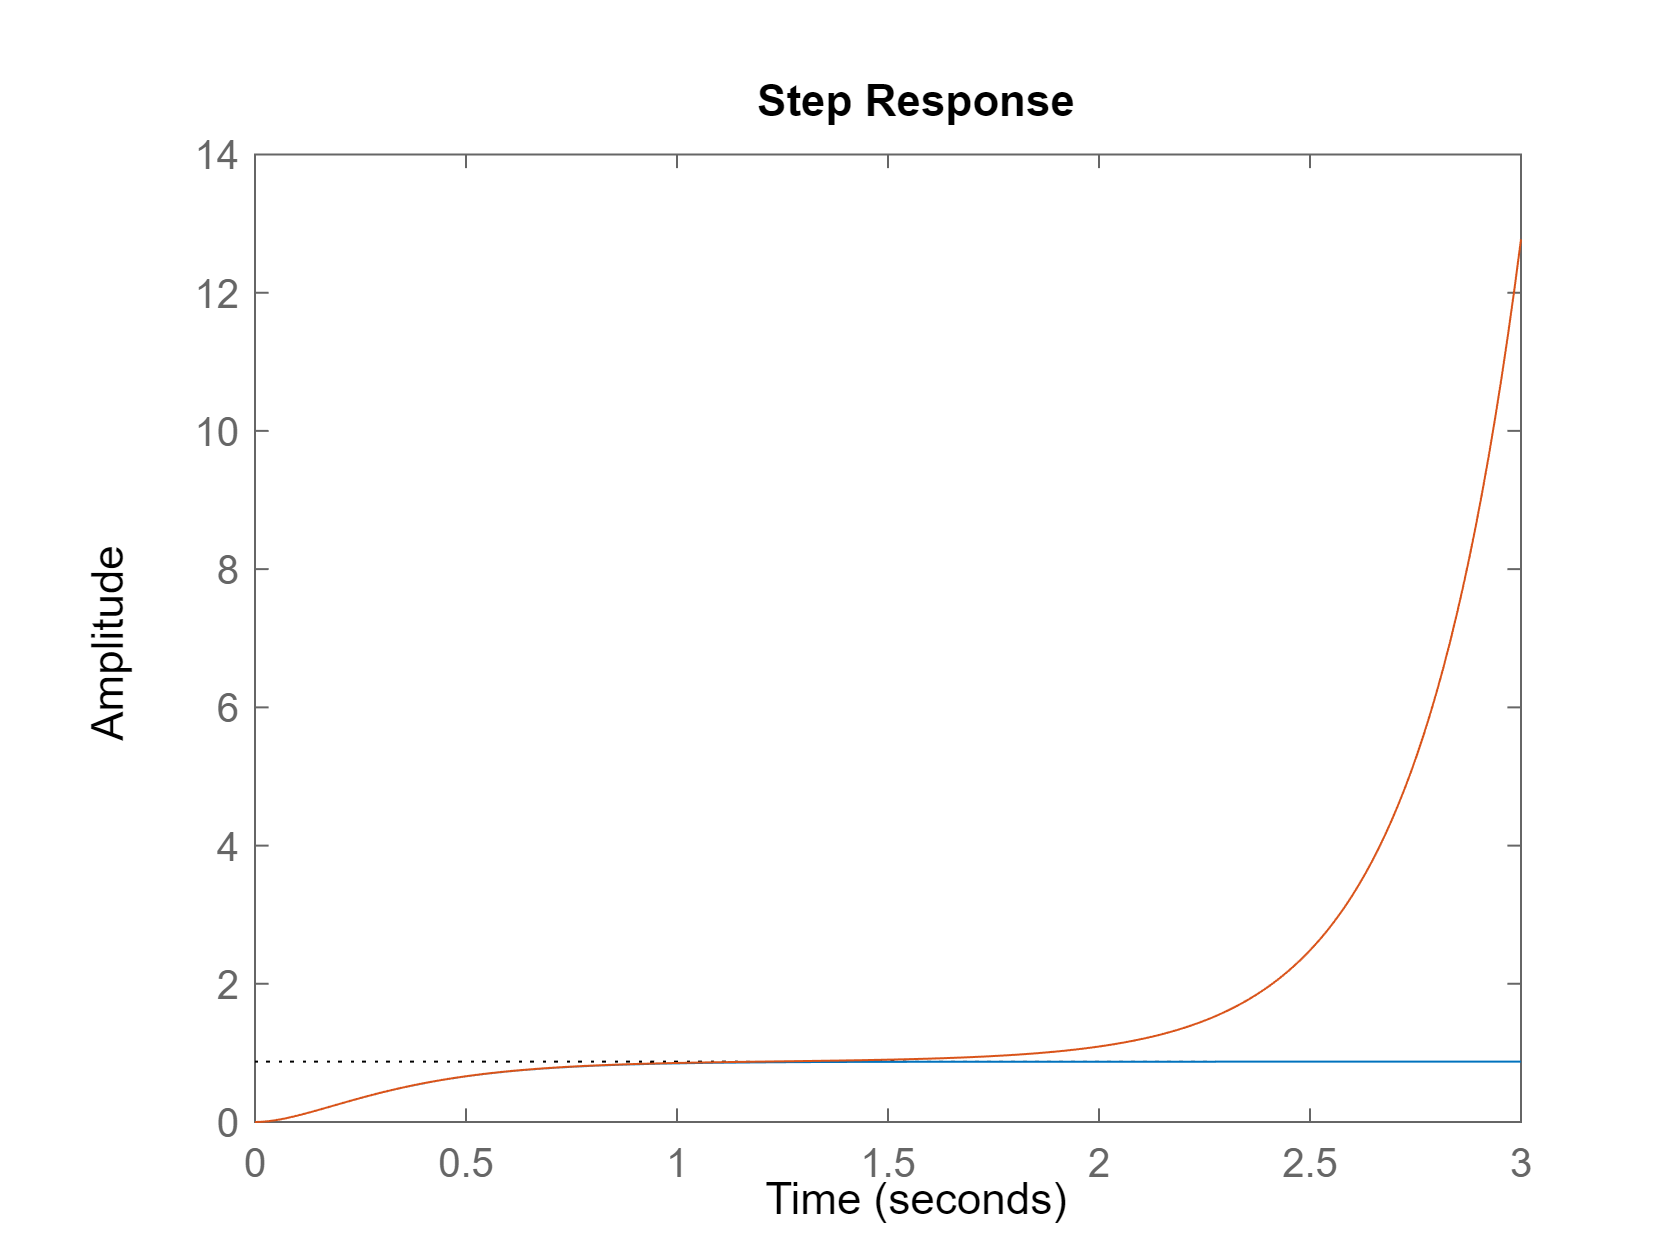

G_cl(s)=collect(G(s)/(1+G(s)))
solve(s^2+a*s+K==0,s)

eq_omega= omega_n^2==K
eq_zeta= 2*zeta*omega_n==a
sol=solve([eq_omega,eq_zeta],[omega_n, zeta])
sol.zeta
K=solve(sol.zeta(1)==zeta,K)

OK lets do things numerically for a specific instance where the system has a pole at $s=-a=-5$

sol = struct with fields:
    omega_n: [2×1 sym]
       zeta: [2×1 sym]


a = 5

G =
 
     1
  -------
  s (s+5)
 
Continuous-time zero/pole/gain model.



pos = 10

zeta = 0.5912

K = 17.8845

Wn = 4.2290

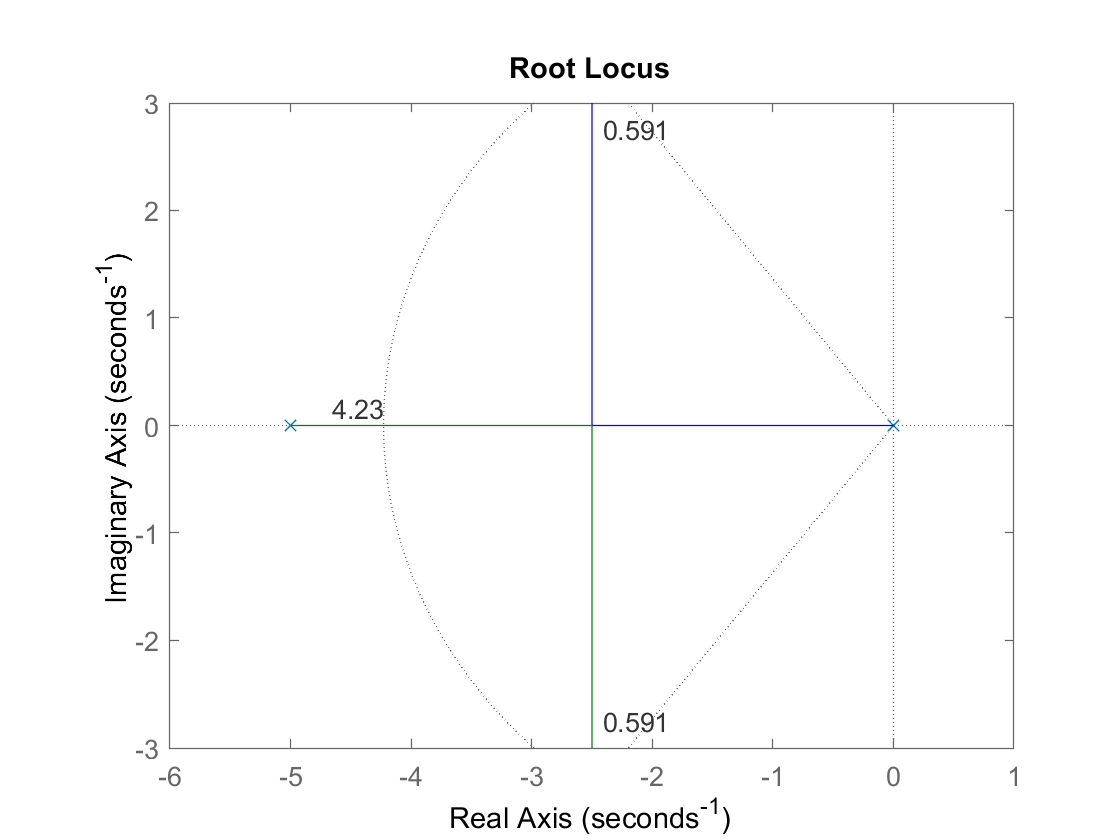

Gcl =
 
        17.885 s (s+5)
  --------------------------
  s (s+5) (s^2 + 5s + 17.88)
 
Continuous-time zero/pole/gain model.



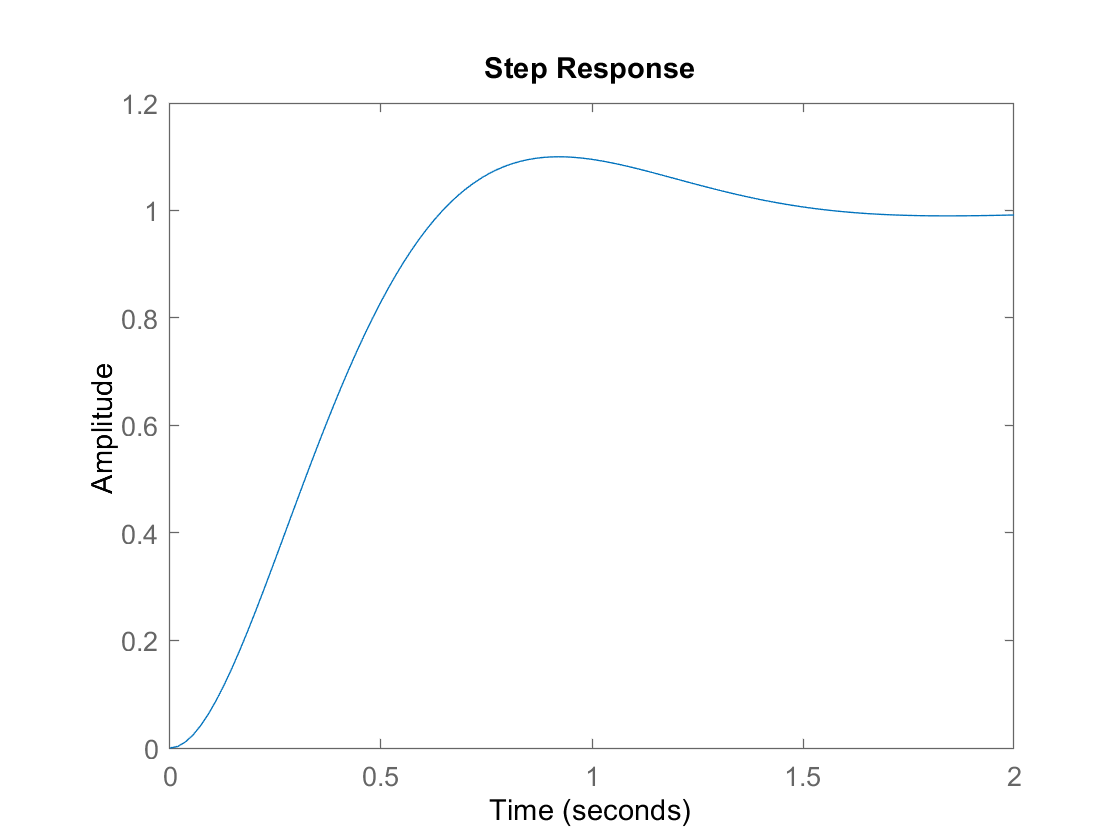

ans = 1.1000

a=5
G=zpk([],[0 -a],1)
pos=10
zeta=-log(pos/100)/sqrt(pi^2+log(pos/100)^2)
K=a^2/(4*zeta^2)
Wn=sqrt(K)

rlocus(G)
sgrid(zeta,Wn)

Gcl=K*G/(1+K*G)
step(Gcl)
[y,t]=step(Gcl);
max(y)
